# Drone Radar Detection Simulation

This example shows how to simulate the drone in a CW radar 

## Parameters

### Constants

Before starting, we need to define some constants avoiding using magic number:

i = sqrt(-1);
c=2.99792458e8;  % light speed
theta=0;  % original initial angle 
sigma=1;  % RCS of the point scatterer
ck=0.200;  % coefficient for SUAV body

where $c$ is the light speed, $\theta$ is the offset, $\sigma$ is the RCS of the point scatterer, $ck$ is the coefficient for the drone body, $i$ is the imaginary unit.

### Drone parameters

Here are some parameters for the drone:

NR=4; % Number of rotors
N = 2; % Number of blades
L1=0.0;
L2 =0.13; % Blade tip to blade root
d1=0.41;% the distance from the origin of the body-fixed coordinates to the point scatterer
v = 0; % SUAV velocity
beta = 0; % elevation angle(degree): 0 - 90
beta = beta*pi/180;  % convert to radian
fr = [150 43 89 74]; % rotation rate: revolution per second
R = 100; % range (m)
consider_drone_body =true;

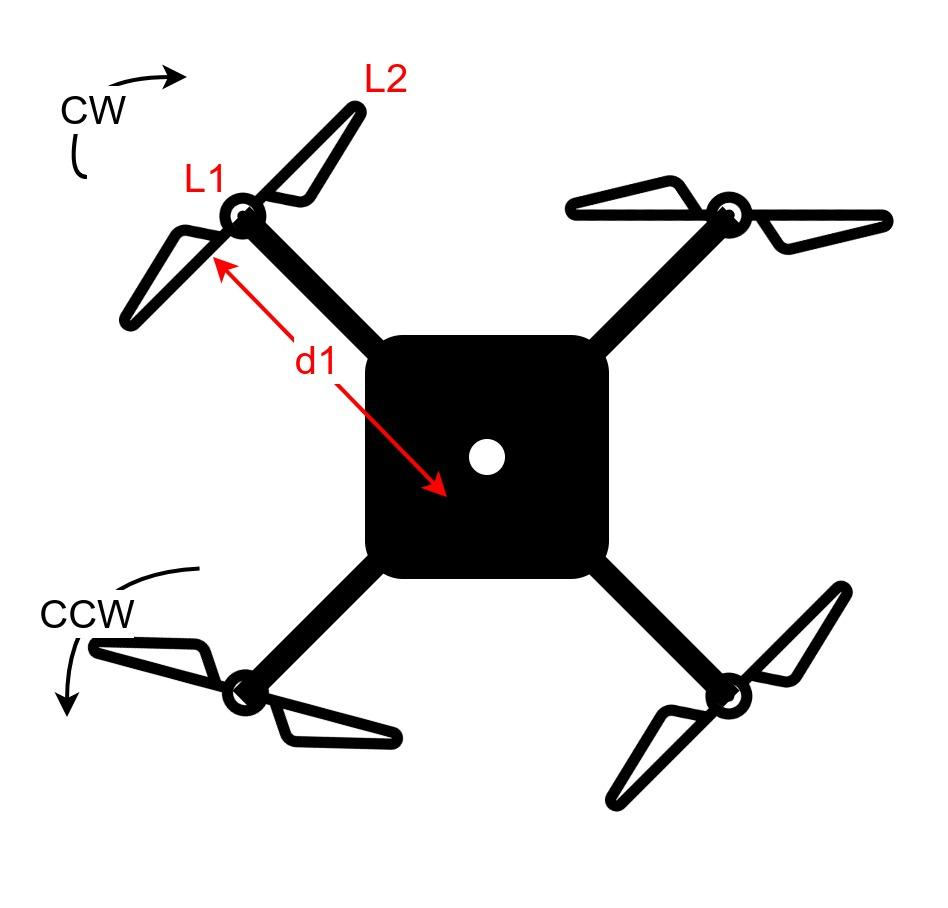            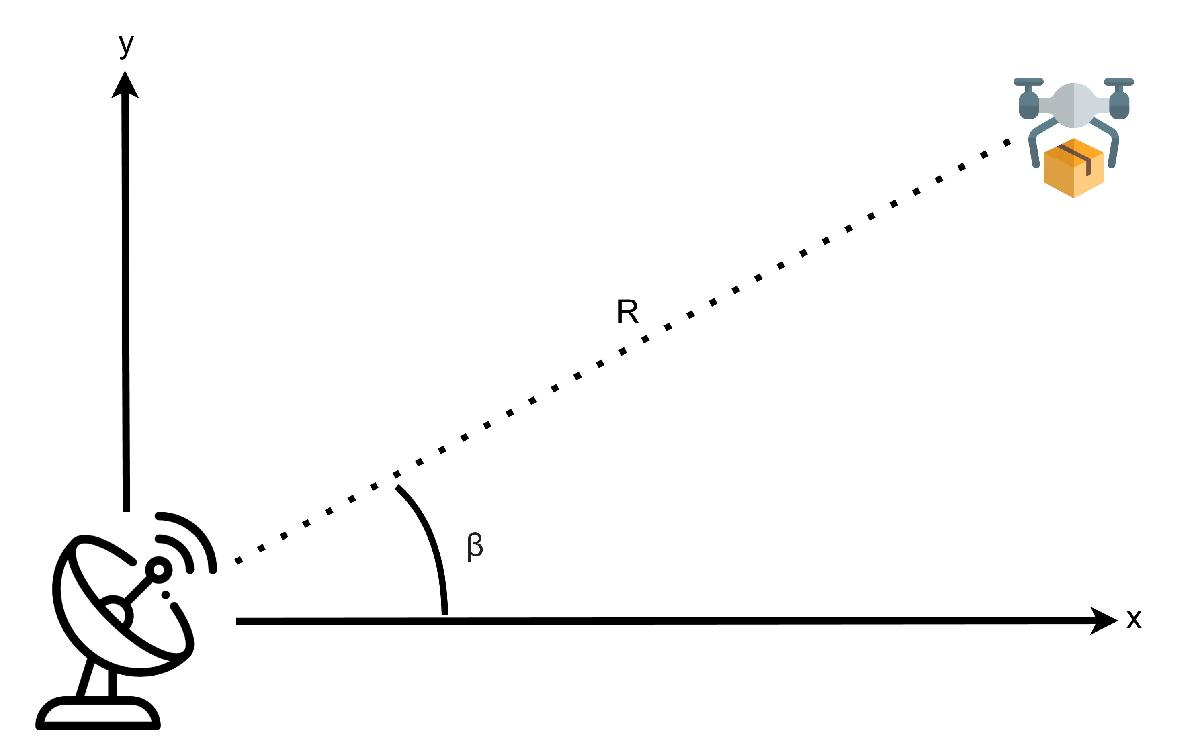

where:

$NR$ is the number of rotors, with value from $\{2,4,6,8\}$;

$N$ is the number of blades for each rotor with value from $[2,4]$;

$L_1$ is the distance $(m)$ from blade root, with value from $(0,1)$;

$L_2$ is the distance $(m)$ from blade root to blade tip, with value from $(0,1)$;

$d_1$ is the distance $(m)$ from blade root to the gravity center of the drone with value from $(0,1)$;

$v$ is the velocity $(m/s)$ of the drone, with value from $[0,50]$;

$\beta$ is the elevation angle $(\degree)$, with value from $[0,90)$;

$f_r$ is the rotation rate (revolution per second) for each rotor, value from $(-\infty,+\infty)$, the postive value means clockwise rotation (CW), the negative value means counterclockwise rotation (CCW), notable, the length of $f_r$ should be same as the $NR$;

$R$ is the range $(m)$ from the radar to the drone; *consider_drone_body* is to indicate that during the simulation, will we consider the reflection from drone body or not.

assert(numel(fr)==NR,"the length of fr should be same as NR (number of rotors).");

### Radar Parameters

Here are some parameters for the radar

NSample =10000;  % Number of samples
fc = 94;  % carrier freq in Ghz
samplerate =200000;  % Sampling Rate: Number of sampling per second, user input

Where  $N_{sample}$ is the total number of samples during a simulation; $f_c$ is the carrier frequency (GHz); $samplerate$ is the number of sampling per second.

## Simulate Return Signal

For each time interval, here is $\Delta t=\frac{1}{samplerate}$, and if we assume the start time point is 0, the time point for each sample can be calculated as $t=\Delta t\cdot NSample_m$, where $m$ represents the m-th sample. 

For the wavelength $\lambda$, here is $\lambda=\frac{c}{f_c}$

the center  of a blade is $l_b = L_2-L_1$

From the EM scattering point of view, 

The distance from the radar to the origin of the reference coordinates is $R_0$, when the speed $v$ is not 0, the $R_0$ for each time point is related to the $R$ and $t$, which can be calculated as $R_0=R+v\cdot t$

The initial rotation angle of the point $P$ at $t = 0$ is $\phi_0$, then at time $t$ the rotation angle becomes $\phi_t= \phi_0+\Omega t$

Thus, for each rotor, the range from the radar to the point scatterer $P$ becomes


$$R_P(t) = \sqrt{R_0^2 + d_1^2 - 2d_1 R_0 \cos(\theta+\theta_r)}$$


where $\theta_r$ is the angle $(\degree)$ between the current rotor and the first rotor, we assume that the angle between each rotor is the same, thus $\theta_r = qrn\frac{360}{NR}$, qrn means the n-th rotor.

The radar observed elevation angles of the origin of the reference coordinates are $\beta$, if the elevation angle $\beta$ are not zero,

the phase function can be modified as

$\Phi_p(t) = \frac{4\pi}{\lambda}[R_p(t)+l_b\cos\beta\sin(2\pi f_r^{qrn}t+2\pi \frac{n_b}{N})]$, where $n_b$ indicated the n-th balde, the $2\pi \frac{n_b}{N}$ indicates the angle (in rad) between the current blade and first blade.

The amplitude of the radar return signal from the blade is


$$AL(t)=\sigma l_b \exp\{i[2\pi f_c t -\Phi_P(t)]\}$$


$X$ is a phase term used within the context of the $\textnormal{sinc}$ function to model the distribution and spread of the radar return over the blade's length. The actual radar return signal from a blade is represented by the combination of $AL$ and the $\textnormal{sinc}$ function applied to $X$, summed up in the $\textnormal{summ}$ variable.


$$X(t) = \frac{4\pi}{\lambda}l_b\cos\beta \sin(2\pi f_r^{qrn}t+2\pi\frac{n_b}{N})$$


the return signal of a blade at the time point will be $S_R(t)=AL(t)\cdot\textnormal{sinc}\bigg(\frac{X_0}{\pi}\bigg)$

Thus, the way we simulate the return signal from drone is as followed:

Vr = complex(zeros(1, NSample));  % the return signal
dt = 1/samplerate;  % time interval
lambda = c/fc;  % wavelength
fc=fc*1e9;  % convert GHz to Hz
for m=1:NSample  % start a for loop to get each sample
    t=dt*(m-1);  % calculate the time point
    summ=0;  % initialize the signal strength as 0 for each sample
    for qrn=1:NR  % start a for loop for each rotor
        for n=1:N  % start a for loop for each blade
            nn=n-1;  % blade is start from 0
            Phi=(4*pi/lambda)*(sqrt((R+(v*t))^2+d1^2-(2*(R+(v*t))*...
                d1*cos((theta+(360/NR*qrn))*pi/180)))+((L1+L2)/2)*...
                cos(beta)* sin(2*pi.*fr(qrn)*t+(2*pi*nn)/N));
            AL=sigma*(L2-L1)*exp(i*(2*pi*fc*t-Phi));
            X=(4*pi/lambda)*((L2-L1)/2)*cos(beta)*sin(2*pi.*fr(qrn)*t+(2*pi*nn)/N);
            summ = summ + (AL*sinc(X/pi));
        end
        if consider_drone_body
            Phi0 = (4*pi/lambda)*(sqrt((R+(v*t))^2+d1^2-(2*(R+(v*t))* ...
                d1*cos((theta+(90* qrn))*pi/180)))+v*t+((L1)/2)* ...
                cos(beta)*sin(2*pi*0*t+(2*pi*nn)/N));
            AL0 = sigma*(ck)*exp(i*(2*pi*fc*t-Phi0));
            X0 = (4*pi/lambda)*((L1)/2)*cos(beta)*sin(2*pi*0*t+(2*pi*nn)/N);
            summ = summ + (AL0*sinc(X0/pi));
        end
    end
    Vr(m) = summ;
end
fc=fc/1e9;  % set it back as origin, so that the usage following will not raise error.

In order to make it more convenient, we encapsulate the above code into a class to facilitate reuse, here is the usage:

figure('Renderer', 'painters');  % change the renderer to painter rather than OpenGL, avoiding the blank of HERM lines
import mypackage.Drone
% colormap(jet(256));
% we create a drone object with certain number of rotors, number of blades, L1, L1, and d1
drone = Drone(NR,N,L1,L2,d1);
% then we generate the return signal
r_94 = drone.generate_return_signal(NSample,v,fc,beta,fr,R,samplerate,consider_drone_body);

Here we draw the Doppler spectrum by Fast Fourier Transform (FFT), which change the return signal from time domain to frequency domain:

### 94GHz with 4 rotors

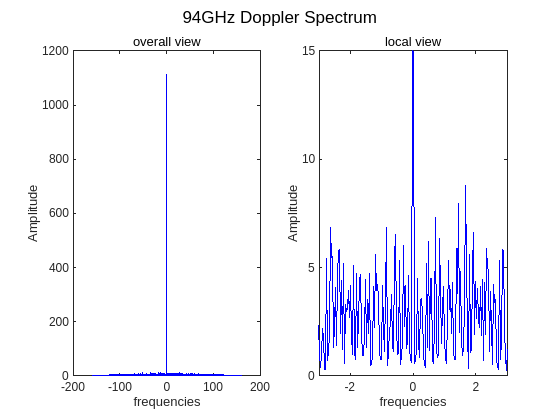

[x_94,fv_94] = drone.generate_doppler_spectrum(r_94);
figure
colormap(jet(256))
subplot(1,2,1)
plot(x_94,fv_94,'b')
xlabel("frequencies")
ylabel("Amplitude")
subtitle("overall view")
subplot(1,2,2)
plot(x_94,fv_94,'b')
xlim([-3 3])
ylim([0 15])
xlabel("frequencies")
ylabel("Amplitude")
subtitle("local view")
sgtitle("94GHz Doppler Spectrum")

### 24GHz

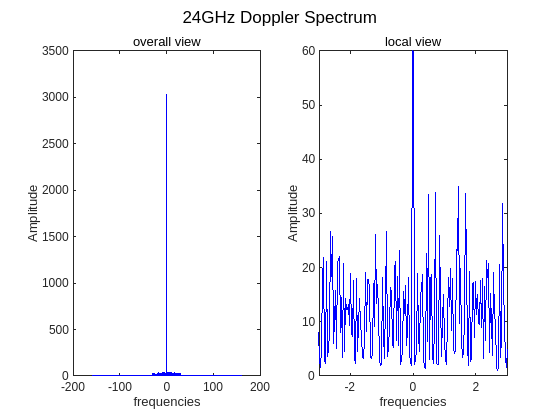

r_24=drone.generate_return_signal(NSample,v,24,beta,fr,R,samplerate,consider_drone_body);
[x_24,fv_24] = drone.generate_doppler_spectrum(r_24);
figure
colormap(jet(256))
subplot(1,2,1)
plot(x_24,fv_24,'b')
xlabel("frequencies")
ylabel("Amplitude")
subtitle("overall view")
subplot(1,2,2)
plot(x_24,fv_24,'b')
xlim([-3 3])
ylim([0 60])
xlabel("frequencies")
ylabel("Amplitude")
subtitle("local view")
sgtitle("24GHz Doppler Spectrum")

### 94GHz with 6 rotors

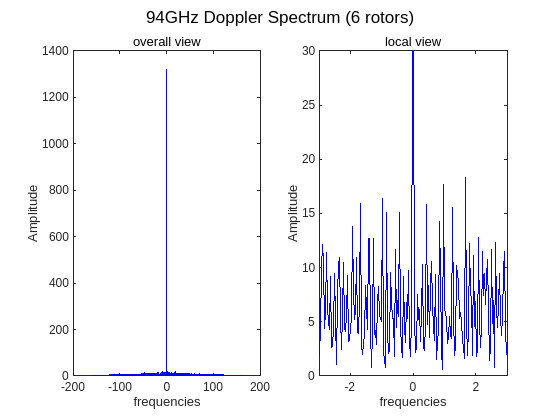

drone_NR6 = Drone(6,N,L1,L2,d1);
r_NR6 = drone_NR6.generate_return_signal(NSample,v,fc,beta,[150 43 89 74 65 13],R,samplerate,consider_drone_body);
[x_NR6,fv_NR6] = drone_NR6.generate_doppler_spectrum(r_NR6);
figure
colormap(jet(256))
subplot(1,2,1)
plot(x_NR6,fv_NR6,'b')
xlabel("frequencies")
ylabel("Amplitude")
subtitle("overall view")
subplot(1,2,2)
plot(x_NR6,fv_NR6,'b')
xlim([-3 3])
ylim([0 30])
xlabel("frequencies")
ylabel("Amplitude")
subtitle("local view")
sgtitle("94GHz Doppler Spectrum (6 rotors)")

## Spectrogram

Then we use the Gaussian kernel to generate the spectrogram by shifting window:

% generate the spectrogram and time range
% --------------------
window_size=64;
np=length(Vr);
ns=np-(window_size-1);
TF=zeros(window_size*2,ns);
win=gausswin(window_size,4);
for k=1:ns
    tmp=win' .* Vr(k:k+window_size-1); %windowing and overlapping
    tmp(length(tmp)+1:length(tmp)*2)=0; %zero padding
    tmp=fft(tmp);
    TF(:,k)=tmp(1:length(tmp));
end
spectrogram=20*log10(fftshift(abs(TF),1)+eps);

### 94GHz with 4 rotors

Overall view:

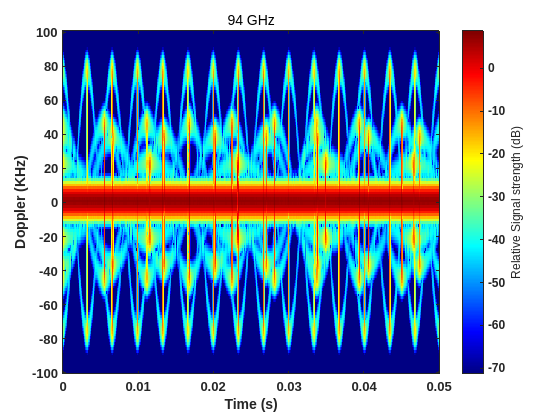

r_94 = drone.generate_return_signal(NSample,v,fc,beta,fr,R,samplerate,consider_drone_body);
[spectrogram_time_range,spectrogram] = drone.generate_spectrogram(r_94,window_size);
drone.draw_spectrogram(spectrogram_time_range,spectrogram);

Local view:

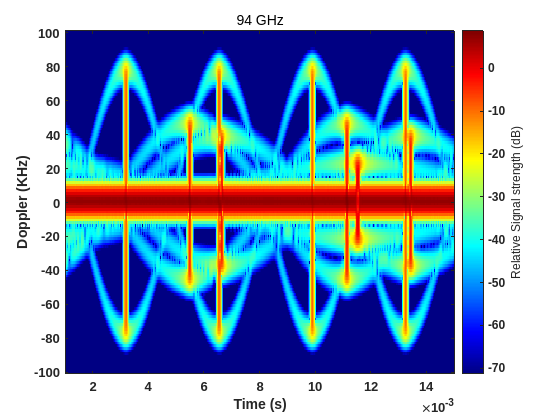

drone.draw_spectrogram(spectrogram_time_range,spectrogram);
xlim([0.0010 0.0150])
ylim([-101 101])

### 24GHz

Overall view:

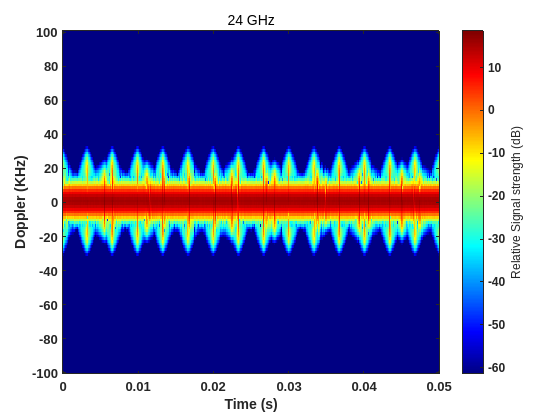

r_24 = drone.generate_return_signal(NSample,v,24,beta,fr,R,samplerate,consider_drone_body);
[spectrogram_time_range,spectrogram] = drone.generate_spectrogram(r_24,window_size);
drone.draw_spectrogram(spectrogram_time_range,spectrogram);

    Local view:

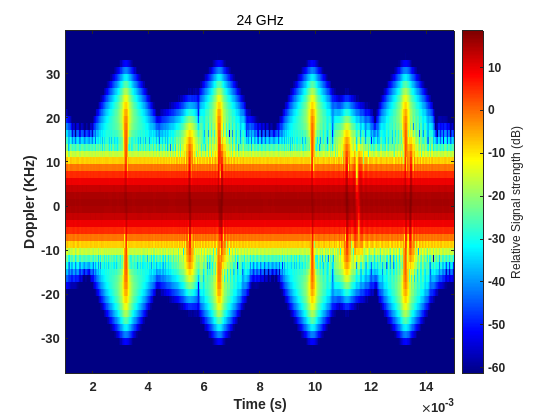

drone.draw_spectrogram(spectrogram_time_range,spectrogram);
xlim([0.0010 0.0150])
ylim([-38.1 39.7])

### 94GHz with 6 rotors

Overall view:

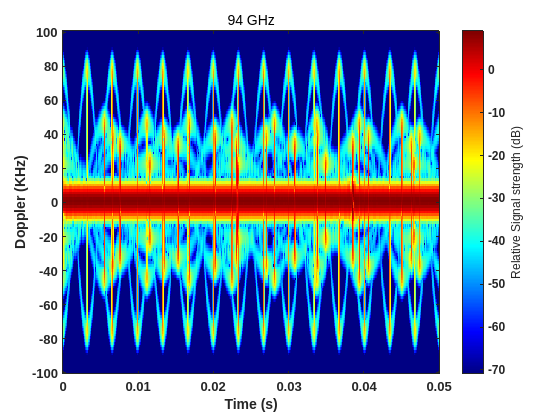

[spectrogram_time_range,spectrogram] = drone_NR6.generate_spectrogram(r_NR6,window_size);
drone_NR6.draw_spectrogram(spectrogram_time_range,spectrogram);

Local view:

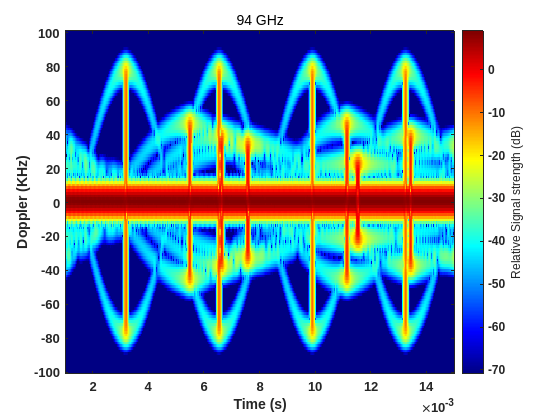

drone_NR6.draw_spectrogram(spectrogram_time_range,spectrogram);
xlim([0.0010 0.0150])
ylim([-101 101])

## HERM line

### 94GHz with 4 rotors

Overall view:

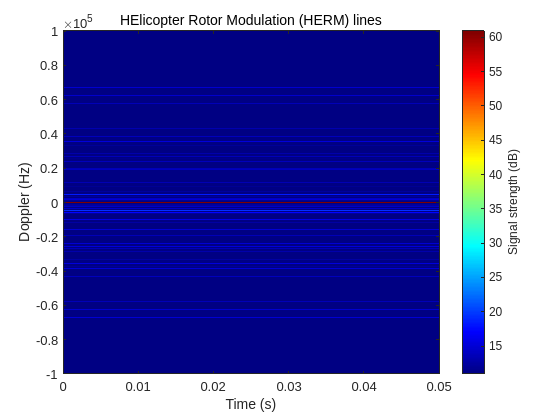

[HERM_time_range,HERM_lines]=drone.generate_HERM_lines(fv_94);
drone.draw_HERM_lines(HERM_time_range,HERM_lines);

Local view:

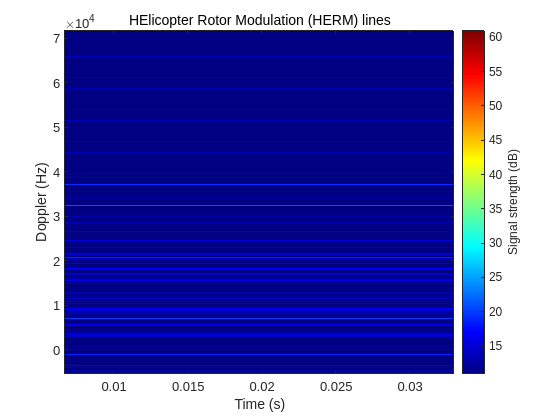

drone.draw_HERM_lines(HERM_time_range,HERM_lines);
xlim([0.0067 0.0330])
ylim([-5464 71669])

### 24GHz

Overall view:

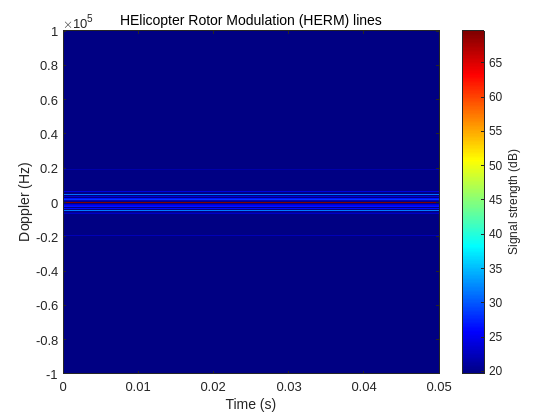

[HERM_time_range,HERM_lines]=drone.generate_HERM_lines(fv_24);
drone.draw_HERM_lines(HERM_time_range,HERM_lines);

Local view:

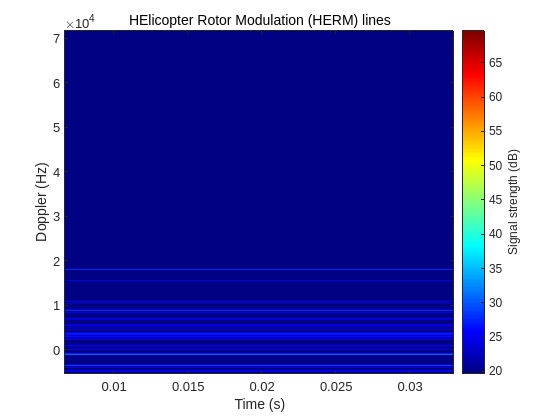

drone.draw_HERM_lines(HERM_time_range,HERM_lines);
xlim([0.0067 0.0330])
ylim([-5464 71669])

### 94GHz with 6 rotors

Overall view:

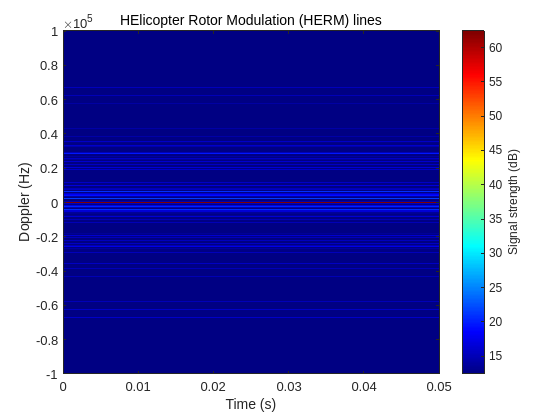

[HERM_time_range_NR6,HERM_lines_NR6] = drone_NR6.generate_HERM_lines(fv_NR6);
drone_NR6.draw_HERM_lines(HERM_time_range_NR6,HERM_lines_NR6);

Local view:

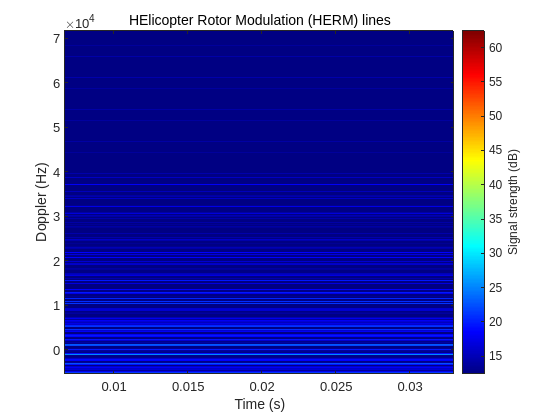

drone_NR6.draw_HERM_lines(HERM_time_range_NR6,HERM_lines_NR6);
xlim([0.0067 0.0330])
ylim([-5464 71669])

## Reference

[1] Chen, V. C. (2019). *The micro-Doppler effect in radar*. Artech house.